# Problem 1

Student 1: Laura Train García

Student 2: Cristina Sánchez Martín

Data of the problem:

clear;clc; close all;

set(gcf,'Visible','on')


% data for the initial point
muE = 398600;                   % mu Earth [km^3/s^2]
h = 2000;                       % altitude [km]
Rearth = 6371;                  % mean radius of Earth[km]

% data for the final point
a = 30000;                      % semi-major axis [km]
e = 0.1;                        % eccentricity
Omega = deg2rad(210);           % RAAN [deg]
inc = deg2rad(25);              % inclination [deg]
omega = deg2rad(36);            % argument of the periapsis [deg]
theta = 2.0944;            % true anomaly [deg]


## Lambert example

% ECI reference frame. i0 coincides with the vernal equinox
i0 = [1; 0; 0];
j0 = [0; 1; 0];
k0 = [0; 0; 1];

% subscript 0 represents the initial circular orbit
% initial position and velocity
R0 = Rearth + h;
theta1 = 0;
r0 = R0*(cos(theta1)*i0 + sin(theta1)*j0);
v0 = -sqrt(muE/R0)*(sin(theta1)*i0 + cos(theta1)*j0);
r1 = r0;

% final position
[r2, ~] = coe2rv(muE, a, e, Omega, inc, omega, theta);

% get ellipse coordinates for initial and final orbits
r1_coords = ellipse_coords(muE, R0, 0, 0, 0, 0);
r2_coords = ellipse_coords(muE, a, e, Omega, inc, omega);

% solve short arc Lambert solution

% r1 = 15945.34*i0;
% r2 = 12214.83899*i0 + 10249.64731*k0;
tf = 1000;

k_short = -cross(r1, r2)/norm(r1.*r2);

[v1, v2, g, f] = Lambert(r1, r2, k_short, tf, muE);

Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight


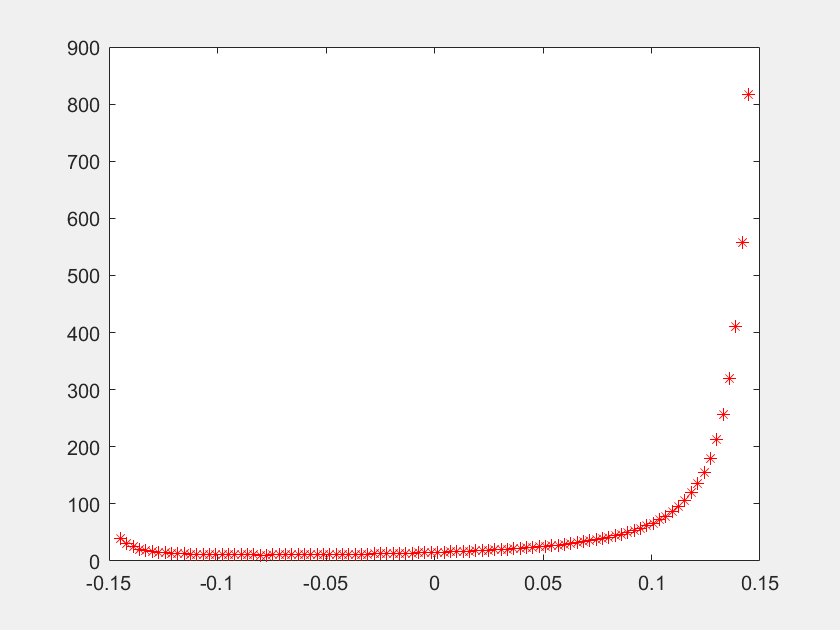


% chord vector
c = r2 - r1;

% eccenticity projection along ic
eF = (norm(r2) - norm(r1))/norm(c);

eTfinal = sqrt(1 - eF^2);
    
eT = linspace(-eTfinal + 0.01, eTfinal - 0.01, 100);
for i = 1:length(eT)
    res(i) = f(eT(i));
end

figure(1)
plot(eT, res, 'r*')

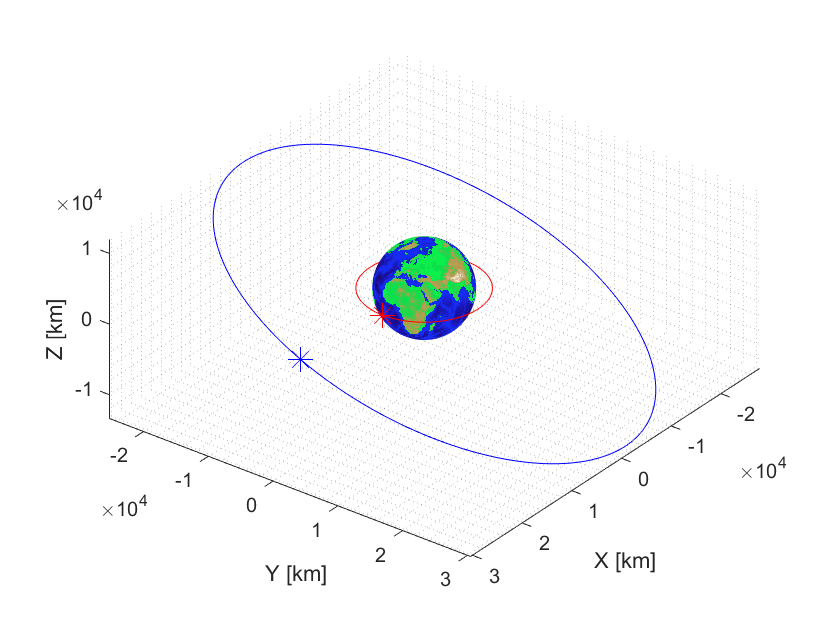

 
figure(2)
earth_sphere('km')
hold on
plot3(r1(1), r1(2), r1(3), 'r*', r2(1), r2(2), r2(3), 'b*', 'MarkerSize',12)
hold on 
plot3(r1_coords(1,:), r1_coords(2,:), r1_coords(3,:), 'r', r2_coords(1,:), r2_coords(2,:), r2_coords(3,:), 'b')
hold off
grid minor
axis equal


[DV] = cost(0,2.0944,0)

Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight


DV = NaN

## Initial exploration

tau = orbital_period(a, muE);
N = 50;
theta1_vec = linspace(0,2*pi,N);
theta2_vec = linspace(0,2*pi,N);
tf_vec = linspace(0,tau,N);
[theta1,theta2,tf] = meshgrid(theta1_vec, theta2_vec, tf_vec);

DV = zeros(N,N,N);
for i = 1:N
    for j = 1:N
        for k = 1:N
            DV(i,j,k) = cost(theta1(i,j,k),theta2(i,j,k),tf(i,j,k));
        end
    end
end

Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) an

## Optimization of the transfer

Explanation of what you do, why and how...

% ...

## Discussion

(Complete your report)